clear all;

if ~isfile('captcha_hard_data.mat') 
    % Import all images with their labels
    path = "reCAPTCHA/images/hard/";
    files_png = dir(fullfile(path,"*.png"));
    num_of_png_imgs = numel(files_png);
    files_jpg = dir(fullfile(path,"*.jpg"));
    num_of_jpg_imgs = numel(files_jpg);    
    images_png = {};
    labels_png = {};
    images_jpg = {};
    labels_jpg = {};
    for i = 1:num_of_png_imgs
        filepath = fullfile(path, files_png(i).name);
        str = strsplit(files_png(i).name, '.');
        labels_png = [labels_png, str{1}];
        img = rgb2gray(imread(char(filepath)));
        images_png = [images_png, img];
    end
    for i = 1:num_of_jpg_imgs
        filepath = fullfile(path, files_jpg(i).name);
        str = strsplit(files_jpg(i).name, '.');
        labels_jpg = [labels_jpg, str{1}];
        img = rgb2gray(imread(char(filepath)));
        images_jpg = [images_jpg, img];
    end
    images_hard = [images_png,images_jpg];
    labels_hard = [labels_png, labels_jpg];
    edge_images_hard = {};
    for i=1:size(images_hard, 2)
        edge_images_hard = [edge_images_hard, edge(images_hard{i},'Canny')];
    end
    % Export grey scale images and their labels to file
    save('captcha_hard_data.mat','images_hard', 'labels_hard', 'edge_images_hard')
else
    load('captcha_hard_data.mat')
end

if ~isfile('captcha_easy_data.mat') 
    % Import all images with their labels
    path = "reCAPTCHA/images/easy/";
    files_png = dir(fullfile(path,"*.png"));
    num_of_png_imgs = numel(files_png);
    files_jpg = dir(fullfile(path,"*.jpg"));
    num_of_jpg_imgs = numel(files_jpg);    
    images_png = {};
    labels_png = {};
    images_jpg = {};
    labels_jpg = {};
    for i = 1:num_of_png_imgs
        filepath = fullfile(path, files_png(i).name);
        str = strsplit(files_png(i).name, '.');
        labels_png = [labels_png, str{1}];
        img = rgb2gray(imread(char(filepath)));
        images_png = [images_png, img];
    end
    for i = 1:num_of_jpg_imgs
        filepath = fullfile(path, files_jpg(i).name);
        str = strsplit(files_jpg(i).name, '.');
        labels_jpg = [labels_jpg, str{1}];
        img = rgb2gray(imread(char(filepath)));
        images_jpg = [images_jpg, img];
    end
    images_easy = [images_png,images_jpg];
    labels_easy = [labels_png, labels_jpg];
    edge_images_easy = {};
    for i=1:size(images_easy, 2)
        edge_images_easy = [edge_images_easy, edge(images_easy{i},'Canny')];
    end
    % Export grey scale images and their labels to file
    save('captcha_easy_data.mat','images_easy', 'labels_easy', 'edge_images_easy')
else
    load('captcha_easy_data.mat')
end

% Analysis

a = bwlabel(edge_images_easy{1}) == 1

a = 24×72 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1   1   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

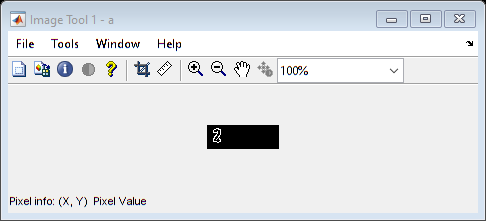

imtool(a)